%data collection

x=zeros(200,20);
y=zeros(200,4);
number1=(3-1).*rand(200,1) + 1;
number2=(3-1).*rand(200,1) + 1;
number3=(3-1).*rand(200,1) + 1;
number4=(3-1).*rand(200,1) + 1;

for i=1:200
c=function_surge(number1(i),number2(i),number3(i),number4(i));

%Y=function_surge1(c);
ans=c';
x(i,:)=c';
y(i,1)=number1(i);
y(i,2)=number2(i);
y(i,3)=number3(i);
y(i,4)=number4(i);

end
x

x =          0         0    0.0055   -0.0493    0.0120   -0.0693    0.0198   -0.0693    0.0263   -0.0493    0.0318         0    0.0291   -0.0472    0.0208   -0.0686    0.0111   -0.0686    0.0028   -0.0472
         0         0    0.0034   -0.0266    0.0072   -0.0363    0.0119   -0.0363    0.0157   -0.0266    0.0191         0    0.0154   -0.0246    0.0117   -0.0360    0.0075   -0.0360    0.0037   -0.0246
         0         0    0.0035   -0.0396    0.0076   -0.0532    0.0125   -0.0532    0.0166   -0.0396    0.0201         0    0.0190   -0.0362    0.0133   -0.0523    0.0068   -0.0523    0.0011   -0.0362
         0         0    0.0034   -0.0386    0.0076   -0.0545    0.0126   -0.0545    0.0168   -0.0386    0.0202         0    0.0235   -0.0356    0.0150   -0.0532    0.0053   -0.0532   -0.0033   -0.0356
         0         0    0.0059   -0.0346    0.0120   -0.0471    0.0198   -0.0471    0.0258   -0.0346    0.0317         0    0.0233   -0.0318    0.0185   -0.0475    0.0132   -0.0475    0.0084  

y

y =     1.8129    1.2275    2.8378    1.2465
    2.9036    2.9297    2.4671    2.4718
    2.8240    1.8650    1.6023    1.3132
    2.9028    1.1691    1.9911    1.8693
    1.6920    2.4334    1.5163    2.6645
    1.5805    2.0136    2.4657    1.7198
    2.7734    1.6562    1.2335    1.1525
    1.4201    2.5070    2.4921    2.1139
    1.2618    2.6720    2.6196    1.5479
    2.0410    1.5074    2.4905    1.2641



for dont_go_here = []
x=zeros(1,20);
y=zeros(1,4);
%number=(2-1).*rand(200,1) + 1;
%for i=1:200
c=function_surge(2);
c;

%U=[0  0 0.005 -0.0363 0.0105 -0.0500 0.0173 -0.0500 0.0228 -0.0363 0.0278 0 0.0225 -0.0338 0.0170 -0.0497 0.0108 -0.0497 0.0053 -0.0338]'

Y=function_surge1();
Y
ans=c';
x(1,:)=c';
y(1,:)=Y';


x;
y;
end


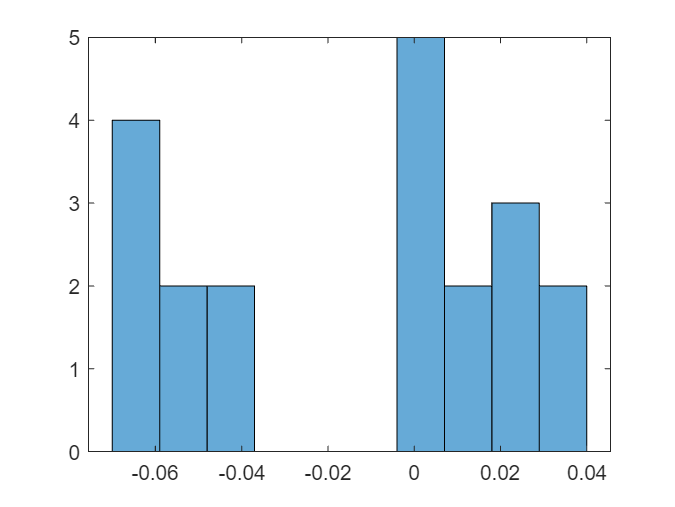

%visualisation of data
histogram(x(1,:),10);

%normalise the features
%for i=1:200
    %x(i,:)=(x(i,:)-min(x(i,:)))/(max(x(i,:))-min(x(i,:)));

%end
%x

%histogram(x(1,:),10);
%x

%training an ANN
hiddenLayerSize =10 ;
net= fitnet(hiddenLayerSize);
net.divideParam.trainRatio=70/100;
net.divideParam.valRatio=30/100;
net.divideParam.testRatio=0/100;
[net,tr]=train(net,x',y');

%performance of the ANN network
xt=x';
yt=y';

yTrain = net(xt(:,tr.trainInd));
yTrainTrue = yt(tr.trainInd);
sqrt(mean((yTrain-yTrainTrue).^2))

ans =     0.6541    1.4827    1.0956    0.9603    0.9584    1.0414    1.0001    0.5560    0.4785    0.7612    0.6542    1.4127    0.5154    0.5368    0.3852    0.6277    0.6441    1.0150    0.6001    1.0390    0.9962    0.8897    0.9752    0.7554    0.8095    0.8593    0.9373    0.5373    0.4246    1.1696    0.3361    0.6283    0.6873    0.5630    0.8027    1.0969    0.4570    1.0566    0.0854    0.9006    1.2212    0.6639    0.3092    0.6467    0.7549    0.5654    0.9135    0.4759    0.6616    0.6912


yVal = net(xt(:,tr.valInd));
yValTrue = yt(tr.valInd);
sqrt(mean((yVal-yValTrue).^2))

ans =     1.0166    0.7653    0.5613    1.1552    0.4467    0.4413    0.5533    0.6979    0.5402    1.0222    0.6399    0.6300    0.5433    0.8384    0.9785    0.9392    0.6274    0.4114    1.1555    0.6881    0.7289    0.6157    0.5641    1.2129    1.1061    0.3202    0.4869    1.1039    1.2412    0.9144    1.1558    0.9493    1.3049    0.4914    0.4925    1.0956    0.8525    1.0272    0.6109    0.4686    0.3610    0.4234    0.5602    0.7549    0.1827    0.5957    1.1241    0.8102    0.3012    0.6362


for dont_go_here = []
 for i=1:60
    %defining the architecture of ANN
    hiddenLayerSize =i;
    net= fitnet(hiddenLayerSize);
    net.divideParam.trainRatio=70/100;
    net.divideParam.valRatio=30/100;
    net.divideParam.testRatio=0/100;
    [net,tr]=train(net,xt,yt);
    %determine the error of the ANN
    yTrain = net(xt(:,tr.trainInd));
    yTrainTrue = yt(tr.trainInd);
   rmse_train(i)= sqrt(mean((yTrain-yTrainTrue).^2))
    yVal = net(xt(:,tr.valInd));
    yValTrue = yt(tr.valInd);
    rmse_val(i)=sqrt(mean((yVal-yValTrue).^2))
 end
end
   

%select the optimal number of neurons in hidden layer
%plot(1:60,rmse_train); hold on;
%plot(1:60,rmse_val); hold off;

%now finding values
 
W=[0  0 0.005 -0.0363 0.0105 -0.0500 0.0173 -0.0500 0.0228 -0.0363 0.0278 0 0.0225 -0.0338 0.0170 -0.0497 0.0108 -0.0497 0.0053 -0.0338]';
y_u=net(W)

y_u =     1.9988
    1.9985
    2.0037
    2.0037



W1=[0  0 0.005 -0.0478 0.011 -0.0683 0.0183 -0.0683 0.0244 -0.0478 0.0294 0 0.0303 -0.0454 0.0204 -0.0672 0.009 -0.0672 -0.0009 -0.0454]';
y_u=net(W1)

y_u =     2.0109
    0.9984
    2.5749
    1.5000
